# Problem 1.

## (a)


$$\pmatrix{x_{1,t+1} \cr x_{2,t+1} \cr x_{3,t+1}} = \pmatrix{0 & 5 & 4 \cr .15 & 0 & 0 \cr 0 & .5 & 0}\pmatrix{x_{1,t} \cr x_{2,t} \cr x_{3,t}}$$


## (b)

close all
A = [0,5,4;.15,0,0;0,.5,0];
x = [100;15;7];

population = zeros(3,101);
eigApprox = zeros(100,1);
population(:,1) = x;
for i = 2:101
    population(:,i) = A * population(:,i-1);
    eigApprox(i-1) = sum(population(:,i),1)/sum(population(:,i-1),1);
end
format long
eigApprox

eigApprox =    1.028688524590164
   1.019521912350598
   1.021688159437280
   1.022088353413655
   1.021077743474600
   1.021975756576235
   1.021362004276435
   1.021722986984773
   1.021534652029946
   1.021621399153594



% Compute total population
population(4,:) = sum(population,1);

figure()
plot(population')
title('Bird Populations over Time')
xlim([0,101])
xlabel('Years')
ylabel('Population')
legend('0-1 Birds','1-2 Birds','2-3 Birds','Total Population','Location','northwest')

The bird populations appear to be growing exponentially. There's no limit to the resources that the birds need to survive. Therefore the bird population can expand faster than they die off.

## (c)

format short
[eigVecs, eigVals] = eig(A);
disp(eigVecs)

  -0.9869 + 0.0000i   0.9358 + 0.0000i   0.9358 + 0.0000i
  -0.1449 + 0.0000i  -0.2442 - 0.0865i  -0.2442 + 0.0865i
  -0.0709 + 0.0000i   0.1857 + 0.1505i   0.1857 - 0.1505i



disp(diag(eigVals,0))

   1.0216 + 0.0000i
  -0.5108 + 0.1810i
  -0.5108 - 0.1810i



The one real eigenvalue is greater than 1. This supports the case of exponential growth. After each year, the total bird population grows by 2%. In part (b) we approximated the growth rate of the total population from year to year. The approximate ratio converged to the true real eigenvalue after 48 years. The complex eigenvalues all have a modulus less than 1 and so they don't affect the limiting trend of the population.

# Problem 2.

## (a)


$$\pmatrix{x_{i,t+1} \cr x_{o,t+1}} = \pmatrix{1 - \frac{2}{10} & \frac{1}{10} \cr \frac{2}{10} & 1 - \frac{1}{10}} \pmatrix{x_{i,t} \cr x_{o,t}}$$


## (b) 

% Construct A and compute eigen decomposition of A
A = [1-0.2, 0.1; 0.2, 1-0.1];
[V,D] = eig(A)

V =    -0.7071   -0.4472
    0.7071   -0.8944


D =     0.7000         0
         0    1.0000


Is $A$ a Markov matrix?

- The second eigenvalue, $\lambda_2$, is equal to 1.

- All the components of the coresponding eigenvector have the same sign. Furthermore, $Av_2 = \lambda_2v_2 = v_2$.

- All of the other eigenvalues are less than or equal to 1.

So, $A$ is a Markov matrix.

## (c) 

% Compute ratio of eigenvalue components
ratio = V(1,2) ./ V(2,2)

ratio = 0.5000

% Simulate steady state solution after 100 years
x = [30;30];
A^100*x

ans =    20.0000
   40.0000


If $x_i$ is the number of people in California and $x_o$ is the number of people outside of California, then the limiting case will satisfy $\frac{x_i}{x_o} = ratio = 0.5$. Furthermore, we know that $x_i + x_o = 60,000,000$. Solving our system of equations yields $x_i = 20,000,00$ and $x_o = 40,000,000$. 

# Problem 3.

## (a) 

Suppose $A$ is diagonalizable, $A = VDV^{-1}$ and $A^m = V D^m V^{-1}$. 

Then


$$e^{At} = I + At + \frac{1}{2!}A^2 t^2 + \frac{1}{3!}A^3 t^3 + \ldots$$



$$= V V^{-1} + VDV^{-1} t + \frac{1}{2!}VD^2V^{-1} t^2 + \frac{1}{3!}VD^3V^{-1} t^3 + \ldots$$



$$= V\left(I + D t + \frac{1}{2!}D^2 t^2 + \frac{1}{3!}D^3 t^3 + \ldots\right)V^{-1}$$



$$= V (e^{Dt}) V^{-1}$$


because $D$ is a diagonal matrix, $e^{Dt}$ becomes

$= V \pmatrix{e^{\lambda_1 t} & 0 & 0 & \cdots & 0 \cr 0 & e^{\lambda_2 t} & 0 & \cdots & 0 \cr 0 & 0 & e^{\lambda_3 t} & \cdots & 0 \cr \vdots & \vdots & \vdots & \ddots &\vdots \cr 0 & 0 & 0 & \cdots & e^{\lambda_n t}} V^{-1}$.

## (b)

% Setup differential equation
N = 100;
t = linspace(0,10,N)';
A = [0, 1; -1, 0];
y0=[1;0];

% Compute eigen decomposition of A
[V, D] = eig(A);

% Preallocate space for solution
y = zeros(2,N);

% Get diagonal entries of D matrix
d = zeros(2,1);
d(1) = D(1,1);
d(2) = D(2,2);

% Compute y(t) for all t
for i=1:N
    y(:,i)= (V * diag(exp(d * t(i))) / V) * y0;
end

plot(t,y(1,:), t, y(2,:))

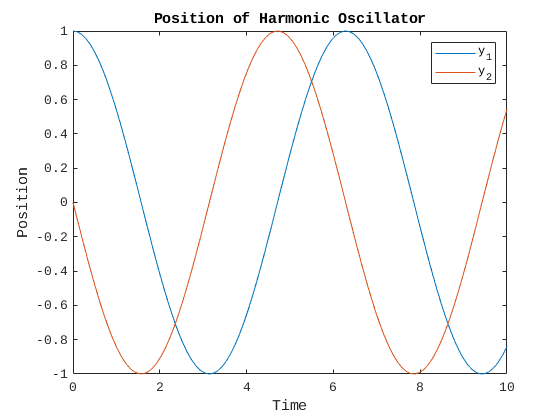

legend('y_1','y_2')
title('Position of Harmonic Oscillator')
xlabel('Time')
ylabel('Position')

The plot confirms that our equation models a mass spring system. We can see that $y_1$ starts at a distance of 1 while $y_2$ starts at 0. From there, both masses begin oscillating about each other.